ObservationInfo = rlNumericSpec([4 1]);
ObservationInfo.Name = 'System States';
ObservationInfo.Description = 'x1, x2, x3, x4';

ActionInfo = rlNumericSpec([2 1]);
ActionInfo.Name = 'System Action';

env = rlFunctionEnv(ObservationInfo,ActionInfo,'myStepFunction','myResetFunction');

rng(0)

cnet = [
    featureInputLayer(4,"Normalization","none","Name","observation")
    fullyConnectedLayer(128,"Name","fc1")
    concatenationLayer(1,2,"Name","concat")
    reluLayer("Name","relu1")
    fullyConnectedLayer(64,"Name","fc3")
    reluLayer("Name","relu2")
    fullyConnectedLayer(32,"Name","fc4")
    reluLayer("Name","relu3")
    fullyConnectedLayer(1,"Name","CriticOutput")];
actionPath = [
    featureInputLayer(2,"Normalization","none","Name","action")
    fullyConnectedLayer(128,"Name","fc2")];

% Connect the layers.
criticNetwork = layerGraph(cnet);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = connectLayers(criticNetwork,"fc2","concat/in2");

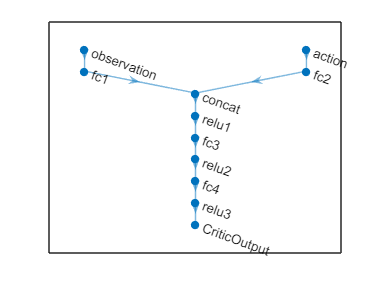

plot(criticNetwork)

criticOptions = rlOptimizerOptions('LearnRate',1e-03,'GradientThreshold',1);

critic = rlQValueFunction(criticNetwork,ObservationInfo,ActionInfo,...
    'ObservationInputNames','observation','ActionInputNames','action');

actorNetwork = [
    featureInputLayer(4,'Normalization','none','Name','observation')
    fullyConnectedLayer(128,'Name','fc1')
    reluLayer('Name','relu1')
    fullyConnectedLayer(64,'Name','fc2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(32,'Name','fc3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2,'Name','fc4')];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions('LearnRate',1e-03,'GradientThreshold',1);

actor = rlContinuousDeterministicActor(actorNetwork,ObservationInfo,ActionInfo);

agentOptions = rlDDPGAgentOptions(...
    'SampleTime',1,...
    'ActorOptimizerOptions',actorOptions,...
    'CriticOptimizerOptions',criticOptions,...
    'ExperienceBufferLength',1e6 ,...
    'DiscountFactor',0.99,...
    'MiniBatchSize',128);
agentOptions.NoiseOptions.Variance = 1e-1;
agentOptions.NoiseOptions.VarianceDecayRate = 1e-6;

agent = rlDDPGAgent(actor,critic,agentOptions);

maxepisodes = 1000;
maxsteps = 500;
trainingOptions = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'StopOnError',"on",...
    'Verbose',false,...
    'Plots',"training-progress",...
    'StopTrainingCriteria',"AverageReward",...
    'StopTrainingValue',-150,...
    'ScoreAveragingWindowLength',25,...
    'SaveAgentCriteria',"EpisodeReward",...
    'SaveAgentValue',-150); 

doTraining = true;
if doTraining      
    % Train the agent.
    trainingResults = train(agent,env,trainingOptions);
end